# MPO 634 - Assignment 02 Spring 2020              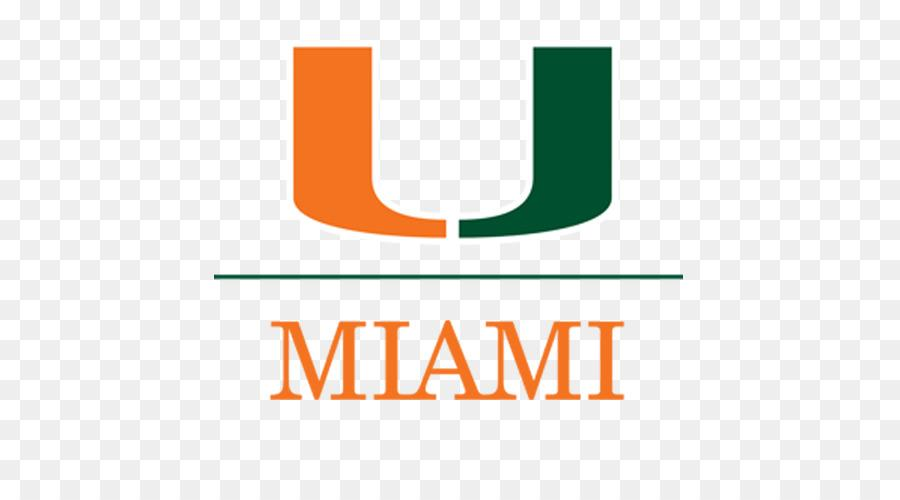

## Ivenis Pita

#### Ivenis, might you be able to use the Matlab code of problem eda06_02.m in the supplemental code .zip file at [this site](https://www.ldeo.columbia.edu/users/menke/edawm/) to do the above exercise: fitting your data as a mean, seasonal cycle, and trend without any need for gap filling.

**d** = **G** **m** + residual

**G'G** = **d'G** **m**

**m** = **(d'G)\(G'G)** in Matlab's clever notation for left-multiplying by an inverse.

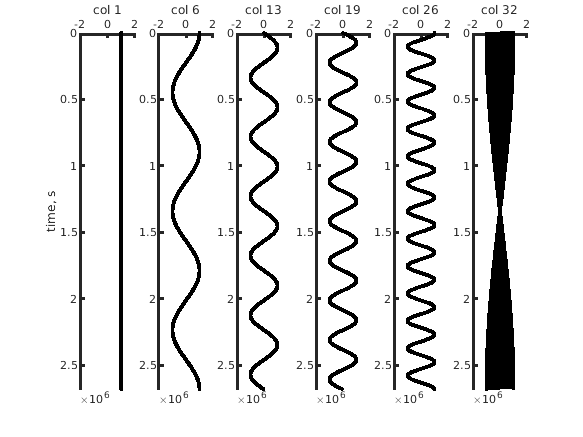

clear variables
close all
clc

stn=50250;%Station ID

%% reading data
load(['/MATLAB Drive/Data_Analysis/Assignment_02/mat_' num2str(stn) '.mat']);clear title
eval(['time=mat_' num2str(stn) '(:,1);'])
eval(['elev=mat_' num2str(stn) '(:,2);'])
clear mat_*

%% organizing time
time=time - 1721058.5;%datenum format
ind_t=time>=datenum([2002 12 1 0 0 0]) & time<=datenum([2003 1 1 0 0 0]);%selecting data from Sep/2002 to Aug/2004
time=time(ind_t);
elev=elev(ind_t);
clear ind_t

time=datestr(time,'dd-mm-yyyy HH');
time=datenum(time,'dd-mm-yyyy HH');
t=min(time):1/24:max(time);
t=datestr(t,'dd-mm-yyyy HH');
t=datenum(t,'dd-mm-yyyy HH');
d=nan(size(t));
[ind1,loc1]=ismember(time,t);
[ind2,loc2]=ismember(t,time);
d(ind2)=elev(ind1);
d=d-nanmean(d);

%Setting matrix length
M=32;%number of frequencies I'd decompose my data
N=length(d);
tt=t; 
clear t

% set up time
Dt=60*60;% [s]
tmin=0.0;
tmax = tmin+Dt*(N-1);
t = tmin + Dt*[0:N-1]';

% nyquist frequencies
%Nf=(Dt)/2;
Nf=N/2+1;
fmax = 1/(2*Dt);
Df = fmax/(N/2);
f = Df*[0:Nf-1]';
Nw=Nf;
wmax = 2*pi*fmax;
Dw = wmax/(N/2);
w = Dw*[0:Nw-1]';

% set up G
G=zeros(N,M);

% zero frequency column
G(:,1)=1;

% interior M/2-1 columns
for i = [1:M/2-1]
    j = 2*i;
    k = j+1;
    G(:,j)=cos(w(i+1).*t);
    G(:,k)=sin(w(i+1).*t);
end

% nyquist column
G(:,M)=cos(w(end).*t);
%G(:,M)=cos(w(Nw).*t);


% plot spectral density
figure(1)
clf;

% plot columns of G vs time
j=1;
for i = [1 round([M/5:M/5:M])]
    subplot(1,6,j);
    j=j+1;
    set(gca,'LineWidth',2);
    hold on;
    set(gca,'XAxisLocation','top');
    axis( [-2, 2, tmin, tmax] );
    axis ij;
    plot( G(:,i), t, 'k-','LineWidth',2);
    plot( G(:,i), t, 'k.','LineWidth',2);
    xlabel(sprintf('col %d',i));
    if (i==1) 
    ylabel('time, s');    
    end
end

## Calculating m and the residual (exp 1)

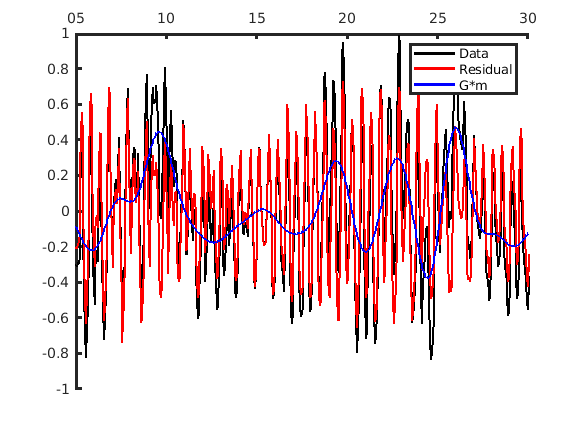

m=(G'*G)\G'*d;
residual=d-G*m;

%% Plot data, predicted and residual
figure(2)
clf
set(gca,'LineWidth',2);
hold on;
set(gca,'XAxisLocation','top');
xlim( [tt(1) tt(end)] );
plot(tt,d,'k-','linewidth',2)
hold on
plot(tt,residual,'r-','linewidth',2)
plot(tt,G*m,'b-','linewidth',2)
legend('Data','Residual','G*m')
datetick('x','dd','keepticks')

%Statistical analysis (Exp1)
e       = d - G * m;
E       = e' * e;
sigmad2 = E / (size(G,1) - size(G,2));
covm    = sigmad2 * inv(G'*G);
sigmam  = sqrt( diag(covm) );
% mlow95  = m - 2*sigmam;
% mhigh95 = m + 2*sigmam;

## Creating a new G matrix with specific frequencies

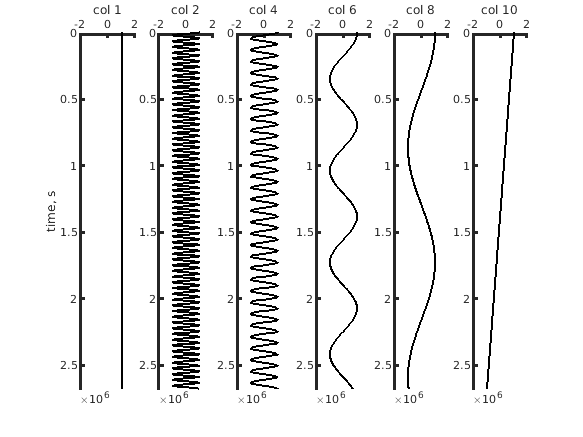

T_specific=[1/2,1,8,20];%days
T_specific=T_specific.*(24*60*60);
f_specific=(1./T_specific);%[Hz]
M=length(f_specific);%number of frequencies I'd decompose my data

% set up G
G1=zeros(N,2+2*M);

% zero frequency column
G1(:,1)=1;

%% interior M/2-1 columns
for i = [1:(M)]
    j = 2*i;
    k = j+1;
    G1(:,j)=cos(2*pi.*f_specific(i).*t);
    G1(:,k)=sin(2*pi.*f_specific(i).*t);
end

%Creating trend
G1(:,end)=[1:-2/(N-1):-1]';

% plot spectral density
figure(3)
clf;

cont=0;
for i = [1 2:2:(2*M) 2*M+2]
    cont=cont+1;
    subplot(1,M+2,cont)
    set(gca,'LineWidth',2);
    hold on;
    set(gca,'XAxisLocation','top');
    axis( [-2, 2, tmin, tmax] );
    axis ij;
    plot( G1(:,i), t, 'k-','LineWidth',2);
%    plot( G1(:,i), t, 'k.','LineWidth',2);
    xlabel(sprintf('col %d',i));
    if (i==1) 
    ylabel('time, s');    
    end
end

## Calculating m and the residual (exp 2)

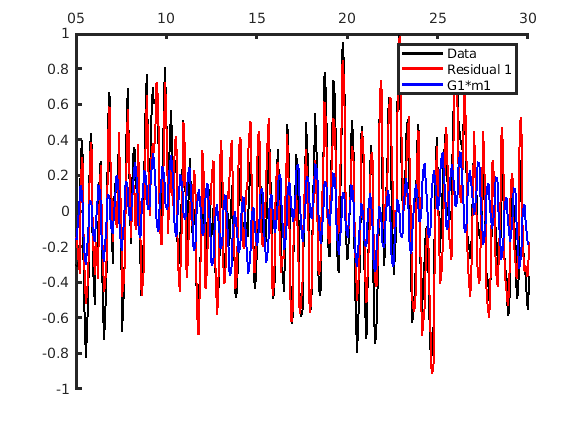

m1=(G1'*G1)\G1'*d;
residual1=d-G1*m1;

%% Plot data, predicted and residual
figure(4)
clf
set(gca,'LineWidth',2);
hold on;
set(gca,'XAxisLocation','top');
xlim( [tt(1) tt(end)] );
plot(tt,d,'k-','linewidth',2)
hold on
plot(tt,residual1,'r-','linewidth',2)
plot(tt,G1*m1,'b-','linewidth',2)
legend('Data','Residual 1','G1*m1')
datetick('x','dd','keepticks')

%Statistical analysis (Exp2)
e_1       = d - G1 * m1;
E_1       = e_1' * e_1;
sigmad2_1 = E_1 / (size(G1,1) - size(G1,2));
covm_1    = sigmad2_1 * inv(G1'*G1);
sigmam_1  = sqrt( diag(covm_1) );
% mlow95_1  = m1 - 2*sigmam_1;
% mhigh95_1 = m1 + 2*sigmam_1;

## Creating gap on the timeseries

n_days=2;%size of the gap in days
gap_start=400;%start of the gap
t1=t;
t1(gap_start:gap_start+24*n_days)=[];
tt1=tt;
tt1(gap_start:gap_start+24*n_days)=[];
d1=d;
d1(gap_start:gap_start+24*n_days)=[];
G2=G1;
G2(gap_start:gap_start+24*n_days,:)=[];
N=length(d1);

## Calculating m and the residual (exp 3 - gappy timeseries)

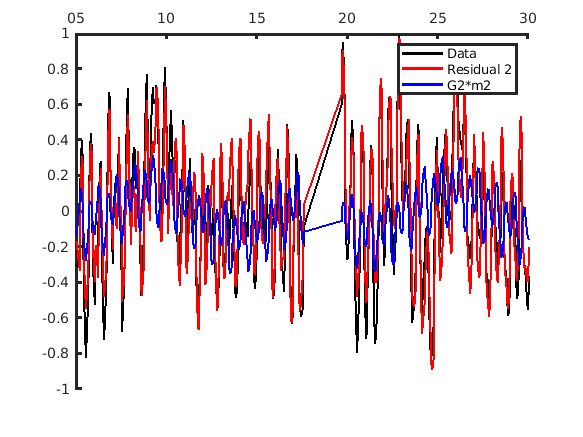

m2=(G2'*G2)\G2'*d1;
residual2=d1-G2*m2;

%% Plot data, predicted and residual
figure(5)
clf
set(gca,'LineWidth',2);
hold on;
set(gca,'XAxisLocation','top');
xlim( [tt1(1) tt1(end)] );
plot(tt1,d1,'k-','linewidth',2)
hold on
plot(tt1,residual2,'r-','linewidth',2)
plot(tt1,G2*m2,'b-','linewidth',2)
legend('Data','Residual 2','G2*m2')
datetick('x','dd','keepticks')

%Statistical analysis (Exp3)
e_2       = d1 - G2 * m2;
E_2       = e_2' * e_2;
sigmad2_2 = E_2 / (size(G2,1) - size(G2,2));
covm_2    = sigmad2_2 * inv(G2'*G2);
sigmam_2  = sqrt( diag(covm_2) );
% mlow95_2  = m2 - 2*sigmam_2;
% mhigh95_2 = m2 + 2*sigmam_2;

## Comparisson between Exp 2 e Exp 3

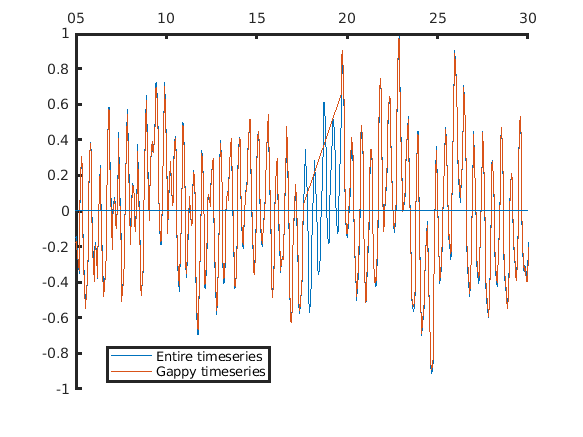

cov_m={covm_1;covm_2;covm};
sigma_d2={sigmad2_1;sigmad2_2;sigmad2};
sigma_m={sigmam_1;sigmam_2;sigmam};

% Residuals
figure(6)
clf
set(gca,'LineWidth',2);
hold on;
set(gca,'XAxisLocation','top');
xlim( [tt1(1) tt1(end)] );
plot(tt,residual1)
hold on
plot(tt1,residual2)
line([tt(1) tt(end)],[0 0])
datetick('x','dd','keepticks')
legend('Entire timeseries','Gappy timeseries','location','best')

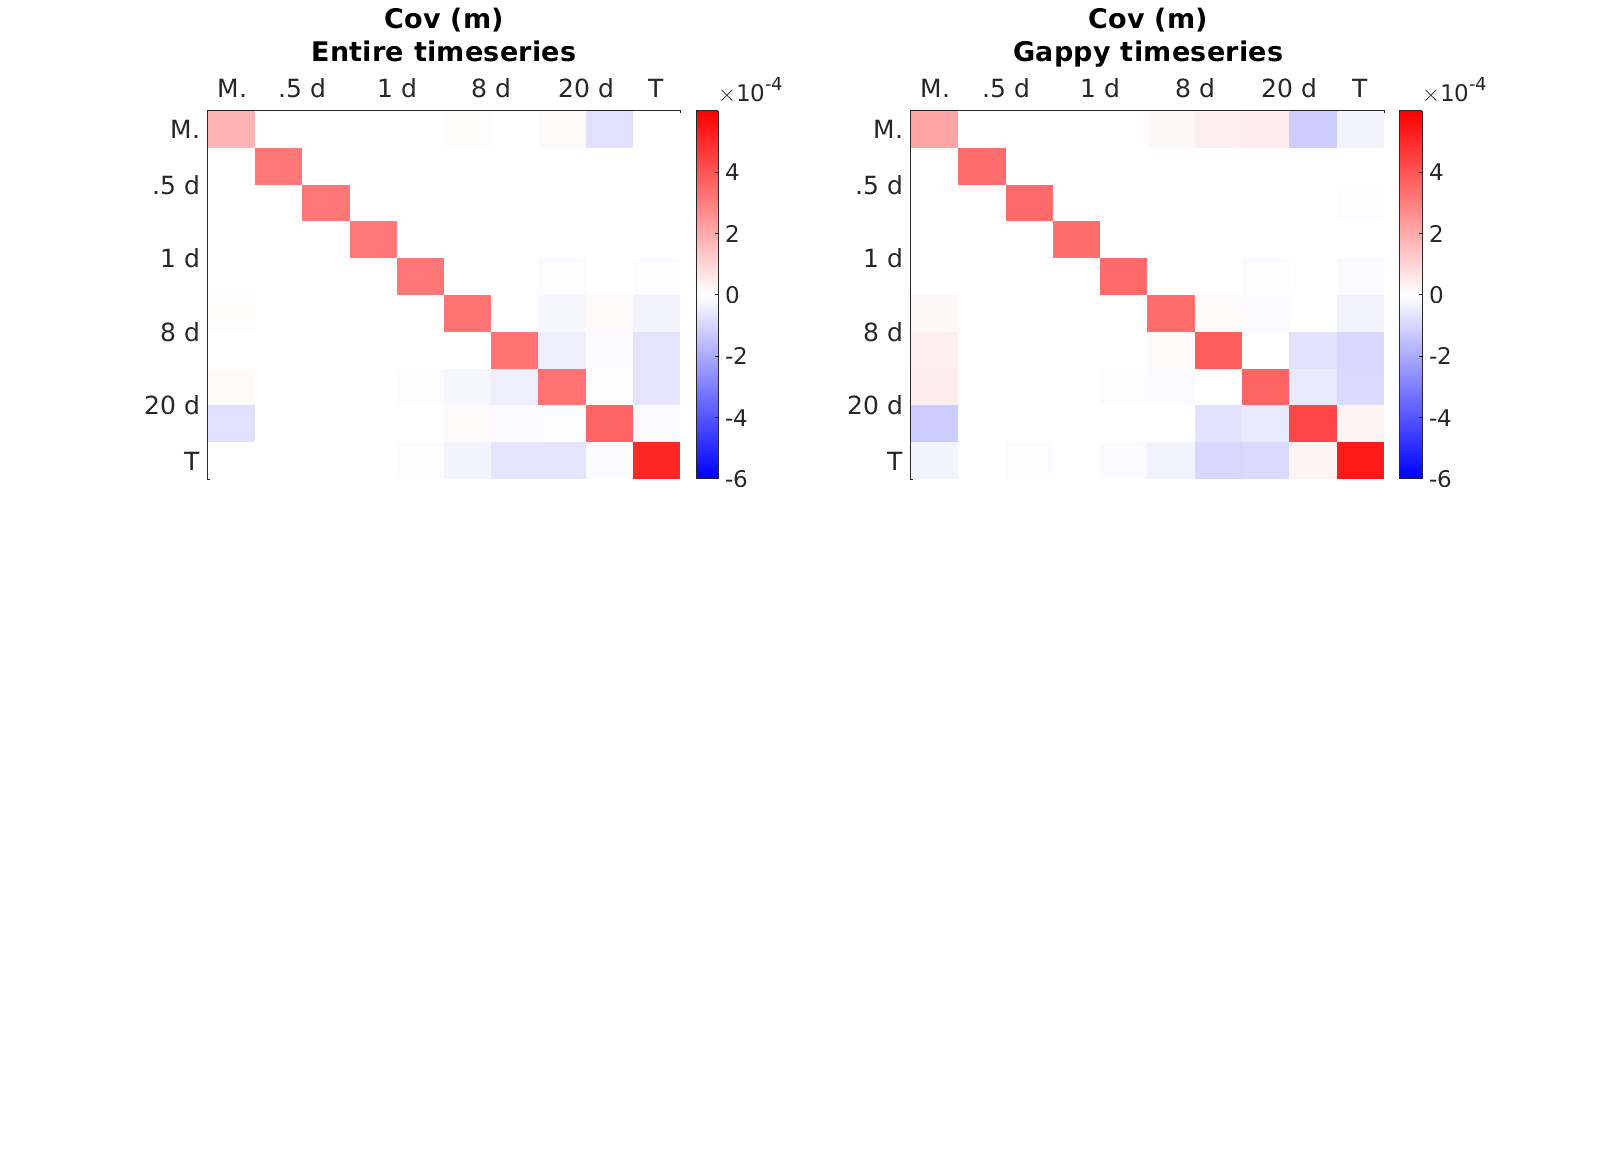

%Cov Matrix
figure(7)
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
subplot(2,2,1)
set(gca,'LineWidth',2);
hold on;
set(gca,'XAxisLocation','top');
axis ij
imagesc(cov_m{1})
ylim([.5 10.5])
xlim([.5 10.5])
xticks([1 2.5 4.5 6.5 8.5 10])
xticklabels({'M.','.5 d','1 d','8 d','20 d','T'})
yticks([1 2.5 4.5 6.5 8.5 10])
yticklabels({'M.','.5 d','1 d','8 d','20 d','T'})
title({'Cov (m)'; 'Entire timeseries'},'FontSize',18)
set(gca,'FontSize',18)
colorbar
colormap(redblue)
caxis([-6e-4 6e-4])

subplot(2,2,2)
set(gca,'LineWidth',2);
hold on;
set(gca,'XAxisLocation','top');
axis ij
imagesc(cov_m{2})
ylim([.5 10.5])
xlim([.5 10.5])
xticks([1 2.5 4.5 6.5 8.5 10])
xticklabels({'M.','.5 d','1 d','8 d','20 d','T'})
yticks([1 2.5 4.5 6.5 8.5 10])
yticklabels({'M.','.5 d','1 d','8 d','20 d','T'})
title({'Cov (m)'; 'Gappy timeseries'},'FontSize',18)
set(gca,'FontSize',18)
colorbar
colormap(redblue)
caxis([-6e-4 6e-4])

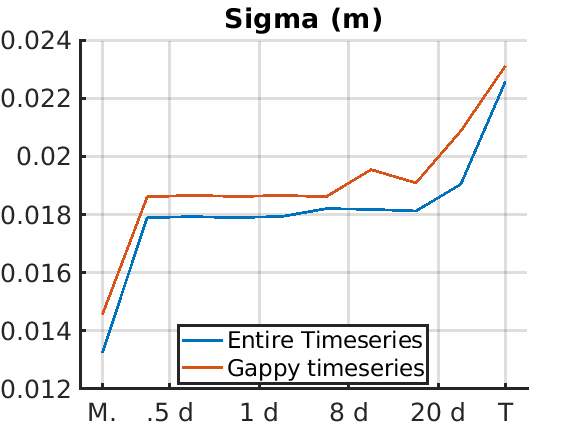

%Sigma m
figure(8)
set(gca,'LineWidth',2);
hold on;
plot(sigma_m{1},'linewidth',2)
hold on
plot(sigma_m{2},'linewidth',2)
xlim([.5 10.5])
xticks([1 2.5 4.5 6.5 8.5 10])
xticklabels({'M.','.5 d','1 d','8 d','20 d','T'})
title('Sigma (m)','FontSize',18)
grid on
set(gca,'FontSize',18)
legend('Entire Timeseries','Gappy timeseries','location','best')